**Analysis of 108 plants **

Load data

% graphics
set(groot,'defaultAxesTickLabelInterpreter','latex');  
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
load('vegfruitanalysis_wholedata.mat')

Remove Water and select only the nutrients with enough data points

Np=10;
matnutrient(strcmpi("Water", nutlist.Nutrient_description),:)=[];
matnutrient=matnutrient(nuttablestat.np>=Np,:);
tlogSD=tlogSD(nuttablestat.np>=Np,:);
tlog=tlog(nuttablestat.np>=Np,:);
nutlistmapping(strcmpi('Water', nutlistmapping.Nutrient_description),:) = [];
tabvizclass=nutlistmapping(nuttablestat.np>=Np, :);
nuttablestat=nuttablestat(nuttablestat.np>=Np,:);

Scaling

%primary metabolism
labelsP={"Thiamin", "Niacin" ,"Phosphorus","Protein", "Carbohydrate"};
labelsP2={"Thiamin", "Niacin", "Phosphorus","Protein", "Carbohydrate"};
%secondary metabolism
labelsS={"Vitamin K (phylloquinone)", "Lutein + zeaxanthin", "Delphinidin"};
labelsS2={"Vitamin K (phylloquinone)", "Lutein + zeaxanthin", "Delphinidin"};


labels=[labelsP, labelsS];
labels2=[labelsP2, labelsS2];

mv=zeros(length(labels),1);
sv=zeros(length(labels),1);
for ind=1:length(labels)
filternut=strcmpi(labels{ind}, nuttablestat.Nutrient_description);
mv(ind)=nuttablestat.muf(filternut);
sv(ind)=nuttablestat.sf(filternut);
disp(labels{ind})
disp([mv(ind), sv(ind)])

end

Thiamin


   1.0e-04 *

    0.6312    0.5791



Niacin


   1.0e-03 *

    0.6236    0.5068



Phosphorus


    0.0367    0.0264



Protein


    1.6246    1.1279



Carbohydrate


   10.0633    7.8446



Vitamin K (phylloquinone)


   1.0e-03 *

    0.0871    0.2226



Lutein + zeaxanthin


    0.0015    0.0031



Delphinidin


    0.0105    0.0235




[~, inds]=sort(mv);
labels=labels(inds);
labels2=labels2(inds);
mv=mv(inds);
sv=sv(inds);


cmap = cbrewer('div','Spectral',height(nuttablestat));

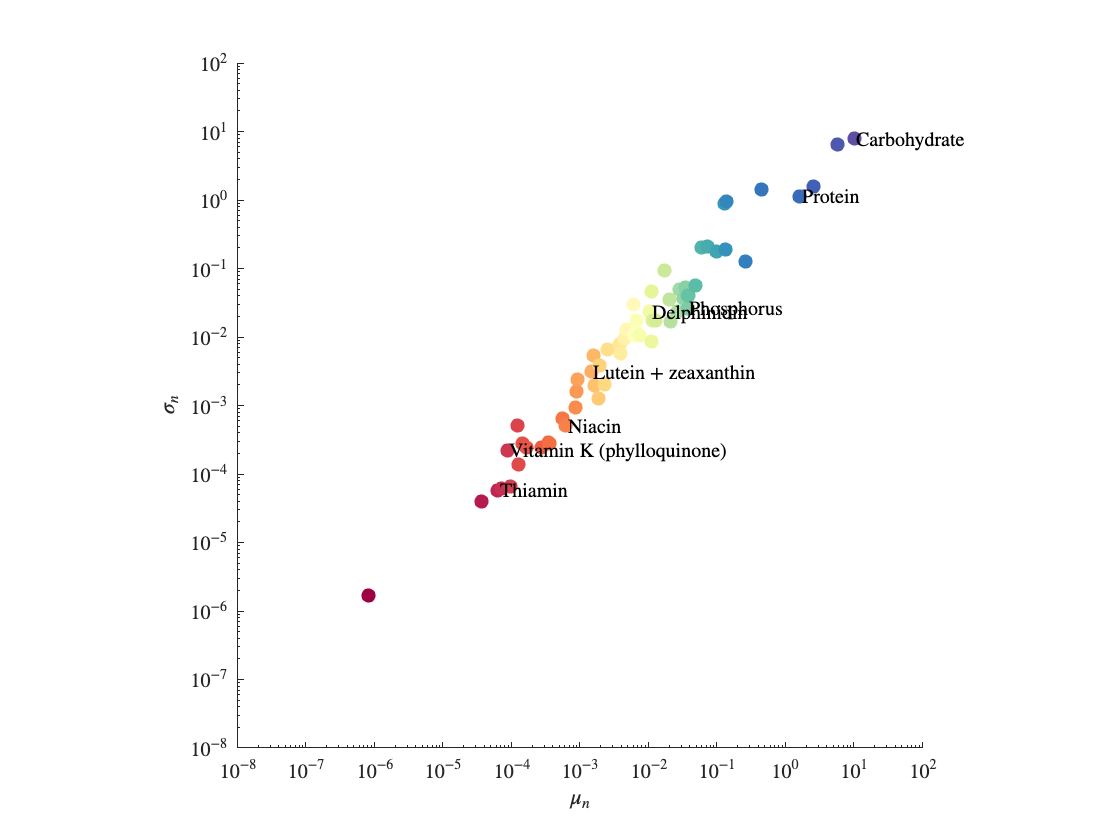

[mufs, inds]=sort(nuttablestat.muf);
sfs=nuttablestat.sf(inds);
lbs=nuttablestat.Nutrient_description(inds);
pslabel=tabvizclass.SUPER_PATHWAY(inds);
nind=zeros(length(labels),1);
for ind=1:length(labels)
nind(ind)=find(strcmpi(labels{ind}, lbs));
end

figure,
scatter(mufs,sfs,50,cmap,'filled')
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
xlabel('$\mu_n$','Interpreter', 'Latex')
ylabel('$\sigma_n$','Interpreter', 'Latex')

hold on

for ind=1:length(labels2)
    text(mv(ind),sv(ind),labels2{ind}, 'FontSize',10,'FontWeight', 'bold')
end



xl=[10^(-8), 10^(-7),10^(-6),10^(-5),10^(-4), 10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2];
xticks(xl)
xticklabels({'$10^{-8}$', '$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;
ax.TickLabelInterpreter  = 'latex';

yticks(xl)
yticklabels({'$10^{-8}$', '$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;
ax.TickLabelInterpreter  = 'latex';
axis square
colorsel=cmap(nind,:);
pssel=pslabel(nind);
axis([xl(1) xl(end) xl(1) xl(end)])



labelsPM=labels(~strcmpi('Secondary metabolism',pssel));
labelsPM2=labels2(~strcmpi('Secondary metabolism',pssel));
labelsSM=labels(strcmpi('Secondary metabolism',pssel));
labelsSM2=labels2(strcmpi('Secondary metabolism',pssel));


colorselPM=colorsel(~strcmpi('Secondary metabolism',pssel),:);
colorselSM=colorsel(strcmpi('Secondary metabolism',pssel),:);

Summary Panel

figure,
C = {{[]};{[]};{[]};{[]};{[]}};
[ha,labelfontsize] = subplotplus(C);


%%%%%%%%%%%
subidx = 1;
set(gcf,'CurrentAxes',ha(subidx));
xl=[10^(-8), 10^(-7),10^(-6),10^(-5),10^(-4), 10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2];
lxl=log(xl);

for ind=1:length(labelsPM)
filternut=strcmpi(labelsPM{ind}, nuttablestat.Nutrient_description);
v=matnutrient(filternut,:);
v=v(v>0);
disp(labelsPM{ind})
disp([mean(log(v)), std(log(v)) ])
h=histogram(log(v), 'normalization', 'pdf', 'EdgeAlpha', 1, 'FaceAlpha', 0.3 );
hold on
centers=h.BinEdges+h.BinWidth/2;
centers=centers(1:end-1);
pdfvalues=h.Values;

hold on
[p1,p2]=normfit(log(v));
x=linspace(min(h.BinEdges), max(h.BinEdges),1000);
y=normpdf(x, p1,p2);
plot(x,y, 'color', [234, 236, 238]/255,'HandleVisibility','off', 'LineWidth',2)
hold on
delete(h)
hold on

if nuttablestat.ischem(filternut)

plot(centers, pdfvalues,'x', 'Color', colorselPM(ind,:),'marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5, 'MarkerFaceColor' ,  colorselPM(ind,:))  
else
plot(centers, pdfvalues,'x', 'Color', colorselPM(ind,:),'marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5)  
    
end


end

Thiamin


   -9.9437    0.7248



Niacin


   -7.6513    0.7676



Phosphorus


   -3.5279    0.6775



Protein


    0.2923    0.6178



Carbohydrate


    2.0861    0.6708



xlabel('$x_n \ (g)$','interpreter','latex')
ylabel('$Q(x_n)$','interpreter','latex')
legend(labelsPM2)
xticks(lxl)
xticklabels({'$10^{-8}$','$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;
c = ax.Color;
ax.TickLabelInterpreter  = 'latex';
axis([lxl(1) lxl(end) 0 0.8])

%%%%%%%%%%%
subidx = 2;
set(gcf,'CurrentAxes',ha(subidx));
xl=[10^(-8), 10^(-7),10^(-6),10^(-5),10^(-4), 10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2];
lxl=log(xl);

for ind=1:length(labelsSM)
filternut=strcmpi(labelsSM{ind}, nuttablestat.Nutrient_description);
v=matnutrient(filternut,:);
v=v(v>0);
disp(labelsSM{ind})
disp([mean(log(v)), std(log(v)) ])
h=histogram(log(v), 'normalization', 'pdf', 'EdgeAlpha', 1, 'FaceAlpha', 0.3 );
hold on
centers=h.BinEdges+h.BinWidth/2;
centers=centers(1:end-1);
pdfvalues=h.Values;

hold on
[p1,p2]=normfit(log(v));
x=linspace(min(h.BinEdges), max(h.BinEdges),1000);
y=normpdf(x, p1,p2);
plot(x,y, 'color', [234, 236, 238]/255,'HandleVisibility','off', 'LineWidth',2)
hold on
delete(h)
hold on

if nuttablestat.ischem(filternut)

plot(centers, pdfvalues,'x', 'Color', colorselSM(ind,:),'marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5, 'MarkerFaceColor' ,  colorselSM(ind,:))  
else
plot(centers, pdfvalues,'x', 'Color', colorselSM(ind,:),'marker', 'o', 'LineStyle', 'none', 'MarkerSize', 5)  
    
end


end

Vitamin K (phylloquinone)


  -11.5386    2.2604



Lutein + zeaxanthin


   -8.5525    2.1600



Delphinidin


   -6.5907    2.2888



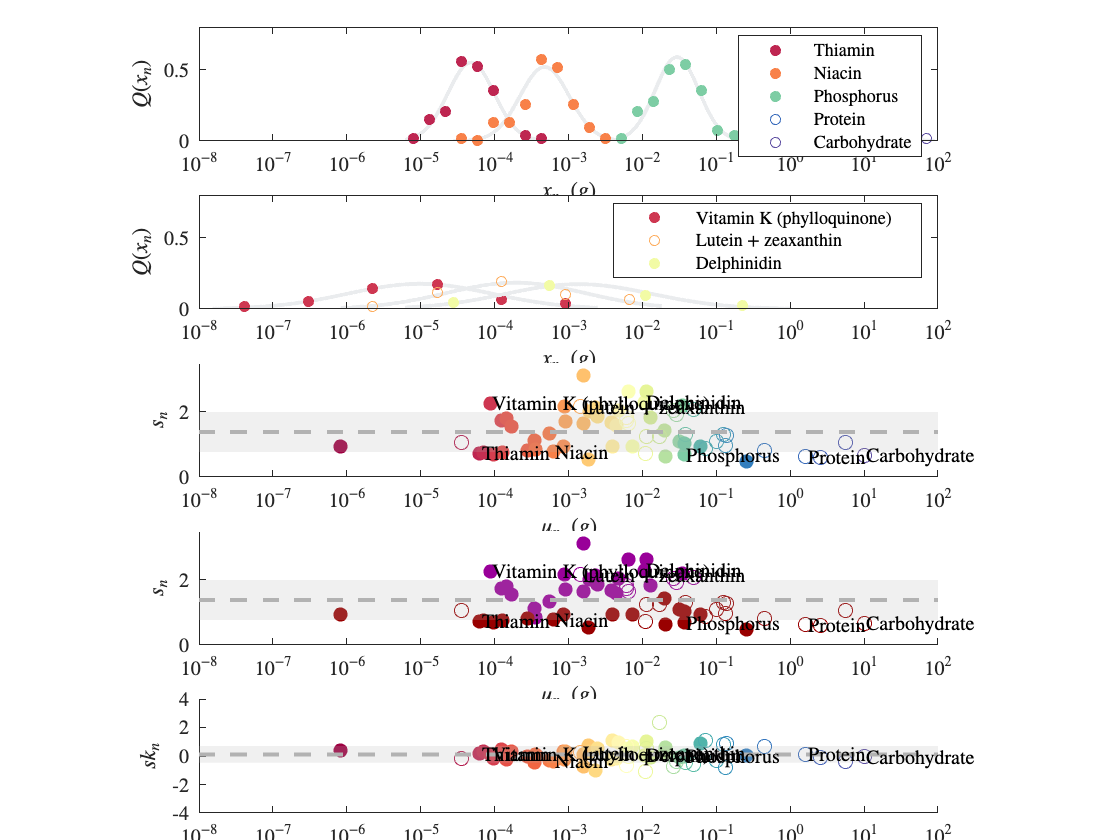

xlabel('$x_n \ (g)$','interpreter','latex')
ylabel('$Q(x_n)$','interpreter','latex')
legend(labelsSM2)
xticks(lxl)
xticklabels({'$10^{-8}$','$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;
c = ax.Color;
ax.TickLabelInterpreter  = 'latex';
axis([lxl(1) lxl(end) 0 0.8])

%%%%%%%%%%%
subidx = 3;
set(gcf,'CurrentAxes',ha(subidx));

xl=[10^(-8), 10^(-7),10^(-6),10^(-5),10^(-4), 10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2];
lxl=log(xl);
tlogSD1 = sortrows(tlogSD,'muf','ascend');


scatter(log(tlogSD1.muf(tlogSD1.ischem)),tlogSD1.sd(tlogSD1.ischem),50,cmap(tlogSD1.ischem,:),'filled')
hold on
scatter(log(tlogSD1.muf(~tlogSD1.ischem)),tlogSD1.sd(~tlogSD1.ischem),50,cmap(~tlogSD1.ischem,:))

xlabel('$\mu_n \ (g)$','Interpreter', 'Latex')
ylabel('$s_n$','Interpreter', 'Latex')
 
 
hold on
 
x=lxl(1):0.001:lxl(end);
Xconf=[x x(end:-1:1)];
ssk=std(tlogSD.sd);
msk=mean(tlogSD.sd)*ones(1,length(x));
mskl=msk-ssk;
msku=msk+ssk;
Yconf=[msku, mskl(end:-1:1)];
 
p = fill(Xconf,Yconf,[178 178 178]/255,'HandleVisibility','off');
p.FaceAlpha=0.2;     
p.EdgeColor = 'none';     
hold on
plot(x, msk, '--', 'LineWidth', 2, 'Color', [178 178 178]/255)

hold on


x=zeros(length(labels),1);
y=zeros(length(labels),1);
for ind=1:length(labels)
filternut=strcmpi(labels{ind}, tlogSD1.Nutrient_description);

x(ind)=log(tlogSD1.muf(filternut));
y(ind)=tlogSD1.sd(filternut);

end

for ind=1:length(labels2)
    text(x(ind),y(ind),labels2{ind}, 'FontSize',10,'FontWeight', 'bold')
end

xticks(lxl)
xticklabels({'$10^{-8}$','$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;
ax.TickLabelInterpreter  = 'latex';
axis([lxl(1) lxl(end) 0 3.5])





%%%%%%%%%%%
subidx = 4;
set(gcf,'CurrentAxes',ha(subidx));

xl=[10^(-8), 10^(-7),10^(-6),10^(-5),10^(-4), 10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2];
lxl=log(xl);
tlogSD1 = sortrows(tlogSD,'muf','ascend');


filterSM=strcmpi('Secondary metabolism', pslabel);

scatter(log(tlogSD1.muf(and(tlogSD1.ischem, filterSM))),tlogSD1.sd(and(tlogSD1.ischem, filterSM)),50,[153, 0, 153]/255,'filled')
hold on
scatter(log(tlogSD1.muf(and(~tlogSD1.ischem, filterSM))),tlogSD1.sd(and(~tlogSD1.ischem, filterSM)),50, [153, 0, 153]/255)


scatter(log(tlogSD1.muf(and(tlogSD1.ischem, ~filterSM))),tlogSD1.sd(and(tlogSD1.ischem, ~filterSM)),50,[153, 0, 0]/255,'filled')
hold on
scatter(log(tlogSD1.muf(and(~tlogSD1.ischem, ~filterSM))),tlogSD1.sd(and(~tlogSD1.ischem, ~filterSM)),50, [153, 0, 0]/255)

xlabel('$\mu_n \ (g)$','Interpreter', 'Latex')
ylabel('$s_n$','Interpreter', 'Latex')
 
 
hold on
 
x=lxl(1):0.001:lxl(end);
Xconf=[x x(end:-1:1)];
ssk=std(tlogSD.sd);
msk=mean(tlogSD.sd)*ones(1,length(x));
mskl=msk-ssk;
msku=msk+ssk;
Yconf=[msku, mskl(end:-1:1)];
 
p = fill(Xconf,Yconf,[178 178 178]/255,'HandleVisibility','off');
p.FaceAlpha=0.2;     
p.EdgeColor = 'none';     
hold on
plot(x, msk, '--', 'LineWidth', 2, 'Color', [178 178 178]/255)

hold on


x=zeros(length(labels),1);
y=zeros(length(labels),1);
for ind=1:length(labels)
filternut=strcmpi(labels{ind}, tlogSD1.Nutrient_description);

x(ind)=log(tlogSD1.muf(filternut));
y(ind)=tlogSD1.sd(filternut);

end

for ind=1:length(labels2)
    text(x(ind),y(ind),labels2{ind}, 'FontSize',10,'FontWeight', 'bold')
end

xticks(lxl)
xticklabels({'$10^{-8}$','$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;
ax.TickLabelInterpreter  = 'latex';
axis([lxl(1) lxl(end) 0 3.5])





%%%%%%%%%%%
subidx = 5;
set(gcf,'CurrentAxes',ha(subidx));
tlog1 = sortrows(tlog,'muf','ascend');

scatter(log(tlog1.muf(tlog1.ischem)),tlog1.sk(tlog1.ischem),50,cmap(tlog1.ischem,:),'filled')
hold on
scatter(log(tlog1.muf(~tlog1.ischem)),tlog1.sk(~tlog1.ischem),50,cmap(~tlog1.ischem,:))

xlabel('$\mu_n \ (g)$','Interpreter', 'Latex')
ylabel('$sk_n$','Interpreter', 'Latex')
 
 
hold on

xl=[10^(-8), 10^(-7),10^(-6),10^(-5),10^(-4), 10^(-3),10^(-2),10^(-1), 10^0 , 10^1, 10^2];
lxl=log(xl);
x=lxl(1):0.001:lxl(end);
Xconf=[x x(end:-1:1)];
ssk=std(tlog.sk);
msk=mean(tlog.sk)*ones(1,length(x));
mskl=msk-ssk;
msku=msk+ssk;
Yconf=[msku, mskl(end:-1:1)];
 
p = fill(Xconf,Yconf,[178 178 178]/255,'HandleVisibility','off');
p.FaceAlpha=0.2;     
p.EdgeColor = 'none';     
hold on
plot(x, msk, '--', 'LineWidth', 2, 'Color', [178 178 178]/255)

hold on

x=zeros(length(labels),1);
y=zeros(length(labels),1);
for ind=1:length(labels)
filternut=strcmpi(labels{ind}, tlog1.Nutrient_description);

x(ind)=log(tlog1.muf(filternut));
y(ind)=tlog1.sk(filternut);

end

for ind=1:length(labels2)
    text(x(ind),y(ind),labels2{ind}, 'FontSize',10,'FontWeight', 'bold')
end
 
hold on
 
xticks(lxl)
xticklabels({'$10^{-8}$','$10^{-7}$','$10^{-6}$','$10^{-5}$','$10^{-4}$', '$10^{-3}$','$10^{-2}$','$10^{-1}$', '$10^{0}$', '$10^{1}$','$10^{2}$'})
ax = gca;

ax.TickLabelInterpreter  = 'latex';
axis([lxl(1) lxl(end) -4 4])